rng(0);
clear;

Download the dataset comprising images of handwritten digits in http://yann.lecun.com/exdb/ mnist; this has been downloaded in the folder “data” and stored as “mnist.mat”. Use the entire training set of 60000 examples. Each image is stored as a matrix (28×28) of numbers. 

You can visualize these images (or matrices) in Matlab using the functions imagesc() or imshow(). Use the Matlab command “axis equal” to use the same units on each axis of the image. 

For the following computations, make sure to convert (cast) the integer data type to a floating-point type. For this question, you cannot use the functions mean(), cov(), and pca() in Matlab. 

For every digit, from 0 to 9, compute: 

load('mnist.mat');
 % array from digit to relevant dataset..
for i = (0:9)
    ddata = digits_train(:,:,labels_train==i);
    dig{i+1} = double(reshape(ddata,28*28,[]));
end
%dig{0+1};% example -> contains all datasets of 0

(i) the mean µ (3 points), 

means = zeros(784, 10); % means kept together
means

means =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


for i = (1:10)
    [a,z] = size(dig{i});
    dmean = sum(dig{i},2)/z;
    %imagesc(reshape(dmean,28,28));
    means(1:784, i) = dmean;
end
means;

(ii) the covariance matrix C (5 points), and 

covs = []; % all covs kept together
for i = (1:10)
    [sx,sy] = size(dig{i});
    dcov = dig{i}*(dig{i}')/(sy-1) - sy*means(:,i)*means(:,i)'/(sy-1);
    covs = cat(3,covs,dcov);
end
covs;

(ii) the principal mode of variation determined by the eigenvector v1 and the corresponding eigenvalue λ1 (where λ1 is the largest of all eigenvalues) of the covariance matrix C (7 points). 

%do it like q3

Note: Before computing the mean and covariance matrix, convert each 28×28 pixel image matrix to a 282 × 1 vector by concatenating its columns. To visualize the 282 × 1 mean vector, convert it back to a matrix and then visualize it using imagesc(). Use the reshape() function to change matrices to vectors and vice versa. The covariance matrix will be of size 282 × 282 . 

• (5 points) For each digit, sort the 282 eigenvalues of the covariance matrix and plot them as a graph. Comment and justify what you observe. 

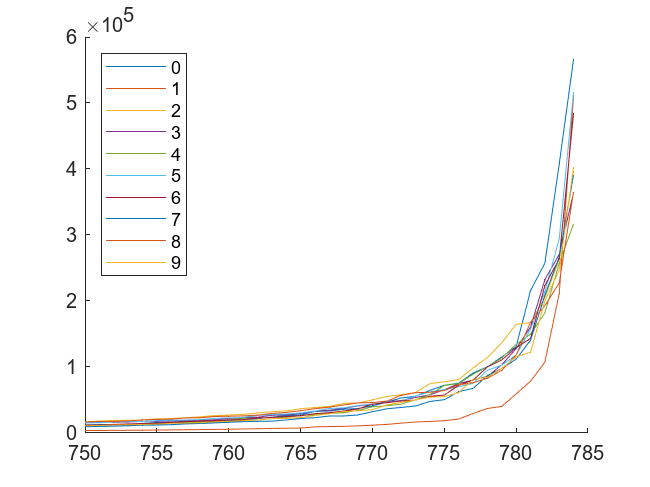

figure
hold on;
for i = (1:10)
    eigens = sort(eig(covs(:,:,i)));
    plot((750:784),eigens(750:784));
end
legend('0','1','2','3','4','5','6','7','8','9','Location','northwest')
hold off;

How many “principal” / significant modes of variation (i.e., number of “large” eigenvalues) do you find, for each digit ? Are the significant modes of variation equal to 282 or far less ? Why ? 

make the graph look useful.

far less - why?

• (5 points) For each digit, show the 3 images side by side: 

(i) µ − √ λ1v1, (ii) µ, and (iii) µ + √ λ1v1,

 to show the principal mode of variation of the digits around their mean. Comment and justify what you observe. For a certain digit, say 1, what does the principal mode of variation tell you about how people write that digit ?

i = 1

i = 2

i = 3

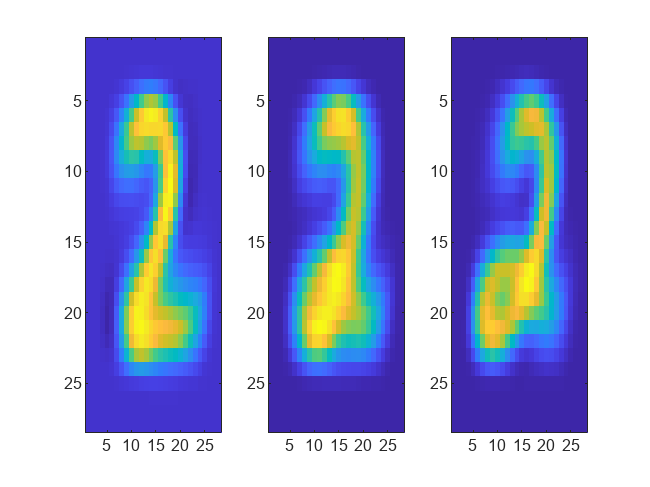

i = 4

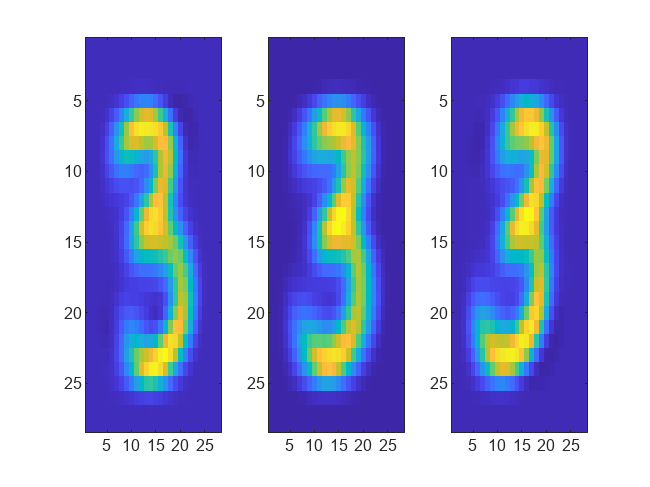

i = 5

i = 6

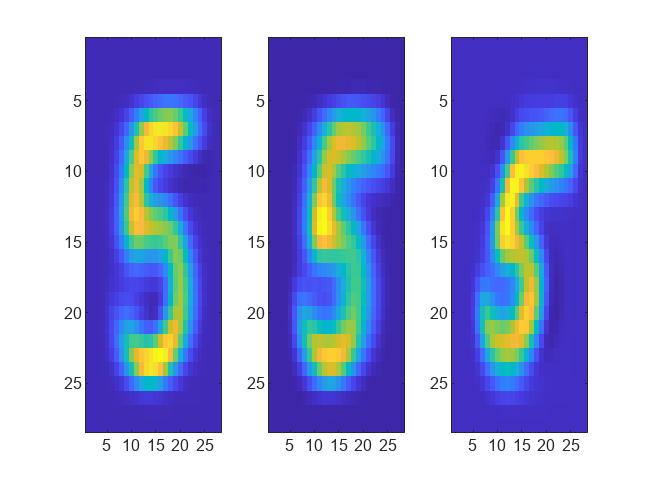

i = 7

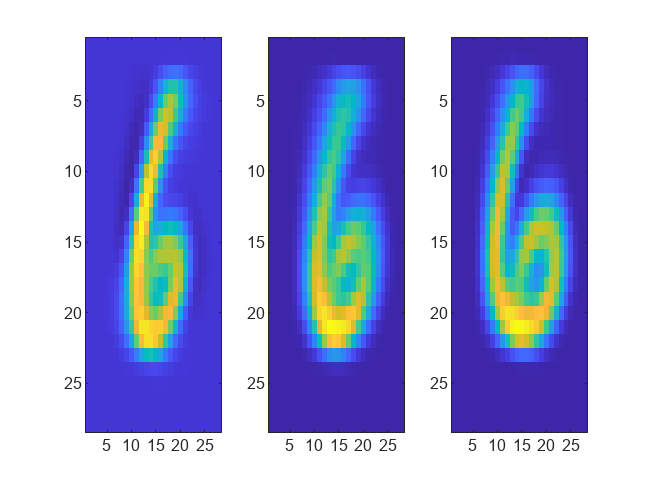

i = 8

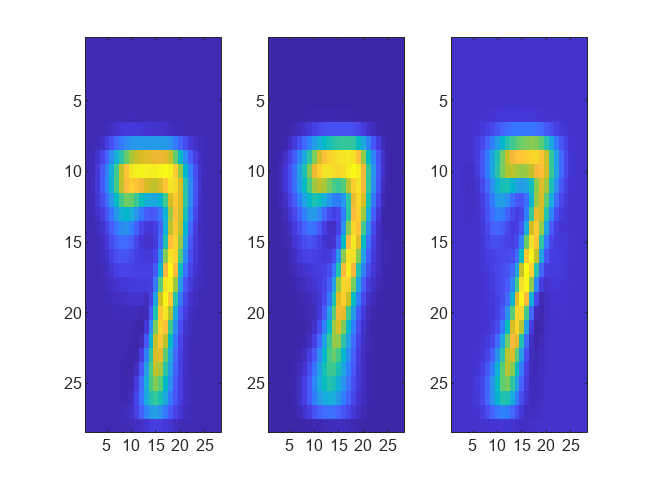

i = 9

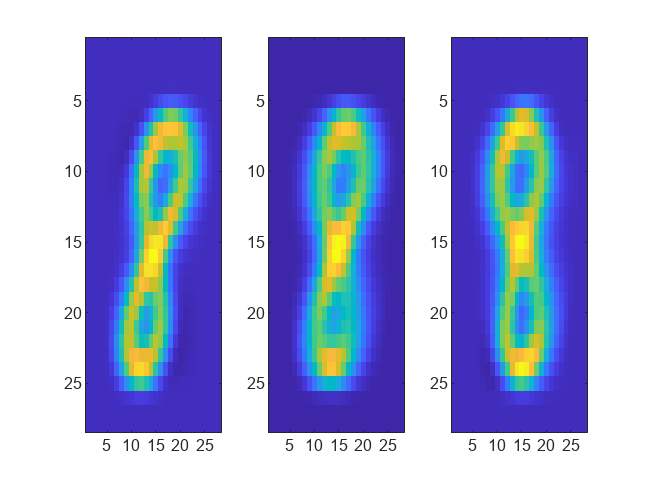

i = 10

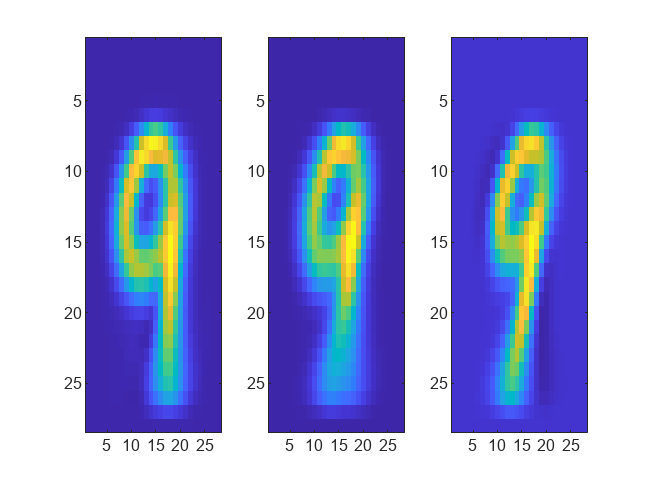

% help why cant i see the digits separately
%figure
for i =(1:10)
    figure(i)
    i
    t = tiledlayout(1, 3);
    [Q,D] = eig(covs(:,:,i));

    %D = diag(D);
    %lv = sqrt(max(D))*Q*(D==max(D));
    %[Q,D] = eig(cov);

    D = abs(diag(D)); 
    [m_temp, i_temp] = max(D);
    w = zeros(length(D),1);
    w(i_temp) = 1 ;   
    v=Q*w;  
    lv = v*sqrt(m_temp);

    %subplot(10,3,3*i-2);
    nexttile
    imagesc(reshape(means(:,i)-lv,28,28));
    
    %subplot(10,3,3*i-1);
    nexttile
    imagesc(reshape(means(:,i),28,28));
    
    %subplot(10,3,3*i);
    nexttile
    imagesc(reshape(means(:,i)+lv,28,28));
    
    
end